## Simulation

### Initialize and run simulation

T_a = Token("TokenA", true, false, 1);
T_b = Token("TokenB", false, true, 0);
initialT_bPrice = 78.32;
totalT_a = 1.2*10^8;
totalT_b = 1.0*10^6;
freeT_a = totalT_a*0.7;
freeT_b = totalT_b*0.7;

walletExpRate = 0.000008;
poolFee = 0.003;
sigma = 0.0001;

baseVirtualPool = 6.7215e7;
poolRecoveryPeriod = 36;
virtualLiquidityPool = OriginalVirtualLiquidityPool(T_a, T_b, initialT_bPrice, ...
    baseVirtualPool, poolRecoveryPeriod);

totalReserves = totalT_a * 0.0001 * 0;

numberOfIterations = 50000;

sim = AlgorithmicStablecoinSimulation(T_a, T_b, initialT_bPrice, ...
    totalT_a, totalT_b, freeT_a, freeT_b, ...
    virtualLiquidityPool, ...
    numberOfIterations, walletExpRate, poolFee, sigma, totalReserves);

[P_a, P_b, probA, probB, delta, totalT_aSupply, totalT_bSupply, ...
    freeT_aRes, freeT_bRes] = sim.runSimulation();

### Plot results

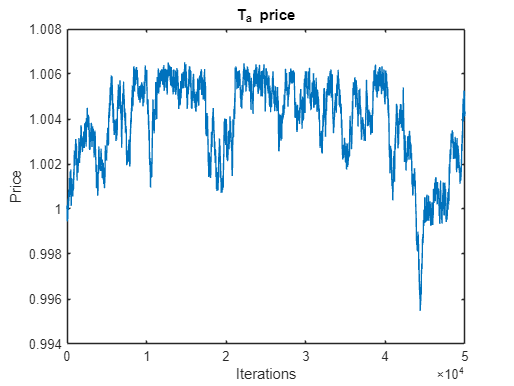

figure;
plot(P_a);
title('T_a price');
xlabel('Iterations');
ylabel('Price');

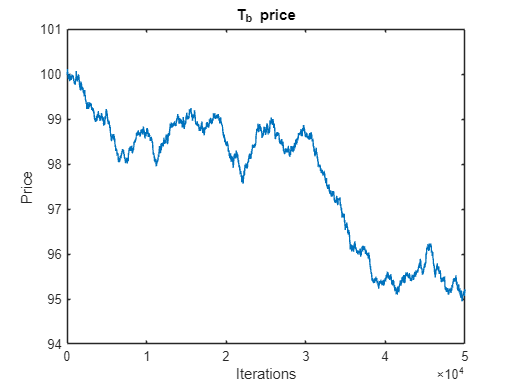

figure;
plot(P_b);
title('T_b price');
xlabel('Iterations');
ylabel('Price');

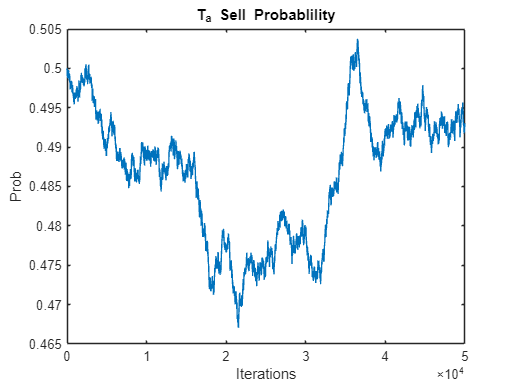


figure;
plot(probA);
title('T_a Sell Probablility');
xlabel('Iterations');
ylabel('Prob');
xlim([0, numberOfIterations]);

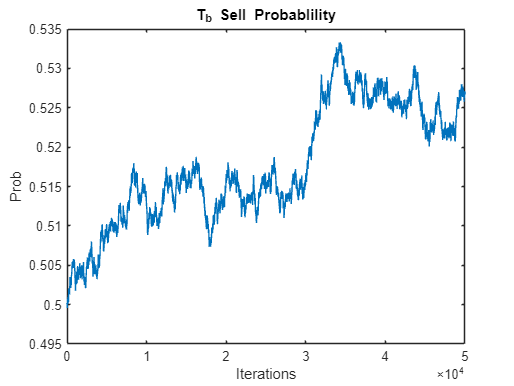

figure;
plot(probB);
title('T_b Sell Probablility');
xlabel('Iterations');
ylabel('Prob');
xlim([0, numberOfIterations]);

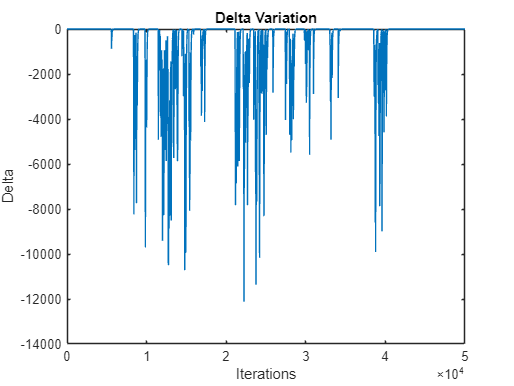


figure;
plot(delta);
title('Delta Variation');
xlabel('Iterations');
ylabel('Delta');
xlim([0, numberOfIterations]);

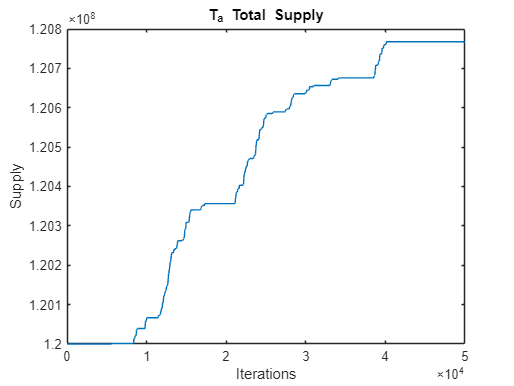


figure;
plot(totalT_aSupply);
title('T_a Total Supply');
xlabel('Iterations');
ylabel('Supply');
xlim([0, numberOfIterations]);

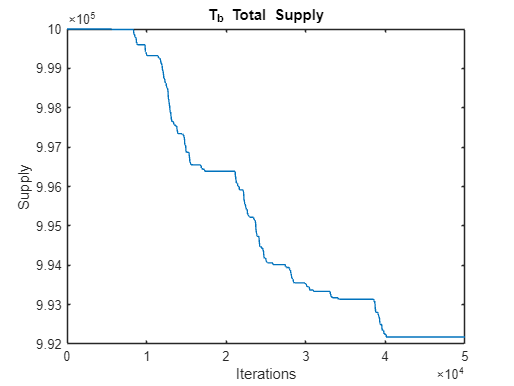

figure;
plot(totalT_bSupply);
title('T_b Total Supply');
xlabel('Iterations');
ylabel('Supply');
xlim([0, numberOfIterations]);

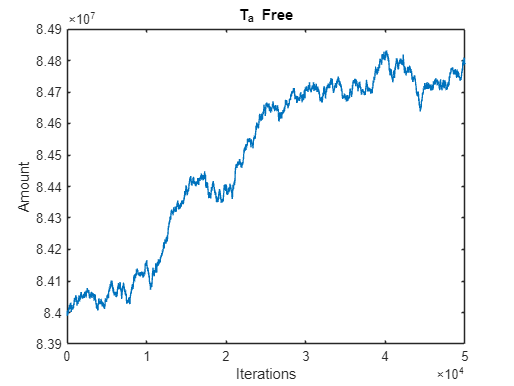


figure;
plot(freeT_aRes);
title('T_a Free');
xlabel('Iterations');
ylabel('Amount');
xlim([0, numberOfIterations]);

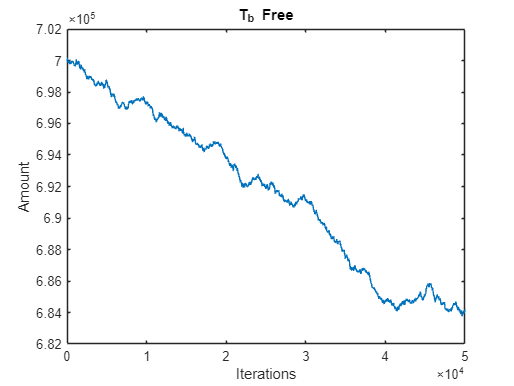

figure;
plot(freeT_bRes);
title('T_b Free');
xlabel('Iterations');
ylabel('Amount');
xlim([0, numberOfIterations]);